**Data Analysis For tidal Data Collected in Kunduchi**

Import data from excel/text file

run Import_data_from_txt_file.m
tidal = data1;

Slice day_1 data for current speed

 day_1 = tidal(76:219,4);

Find the mean current speed for day_1

spd = table2array(day_1);
mean(spd)

ans = 67.1594

plot

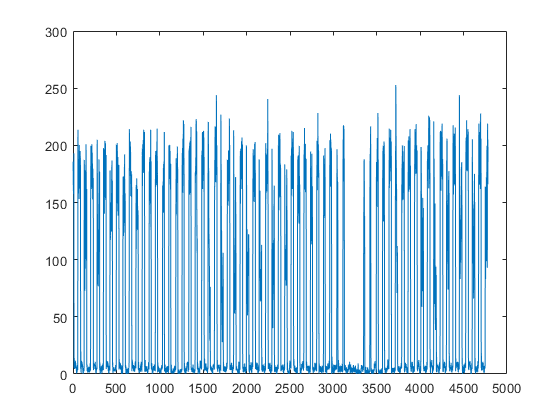

plot(data1.cms)

Cp Plot

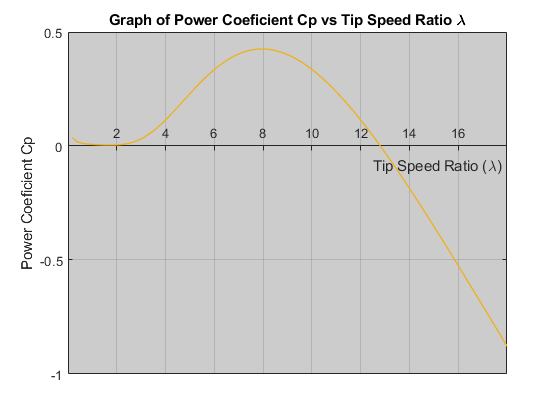

l = linspace(0,18);
b = 0;
x = ((1./(l+0.08*b))-((0.035)/(b^3+1)));
l_i = 1./x;
C_p = (0.5167.*((116./l_i) - (0.4*b) - (5)).*exp(-21./l_i))+(0.0068./l);
tsr_graph(l,C_p)